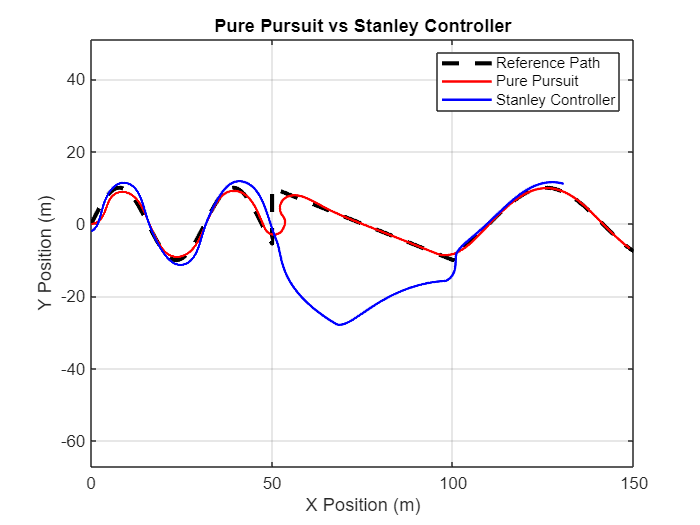

% Pure Pursuit and Stanley Controller Comparison with Complex Path and Varying Speeds
clear all; close all; clc;

% Simulation Parameters
dt = 0.01;                 % Time step
t_final = 60;              % Total simulation time
look_ahead_distance = 5;   % Look-ahead distance for Pure Pursuit
l = 2.5;                   % Vehicle wheelbase (m)
k_stanley = .65 ;           % Adjusted Stanley gain for steering correction

% Complex Path Definition
path_x = [linspace(0, 50, 500), linspace(50, 100, 500), ...
          linspace(100, 150, 500)]; % X-coordinates
path_y = [10*sin(0.2*path_x(1:500)), linspace(10, -10, 500), ...
          10*cos(0.1*(path_x(1001:1500)))]; % Y-coordinates

% Speed Profile (Variable Speeds)
v_profile = [3*ones(1, 2000), 10*ones(1, 1000), 15*ones(1, 300)]; % Speeds at each segment

% Vehicle State Initialization (Pure Pursuit and Stanley)
x_pp = 0; y_pp = 0; yaw_pp = 0; % Initial state for Pure Pursuit
x_stan = 0; y_stan = -2; yaw_stan = 0; % Initial state for Stanley Controller

% Storage for Vehicle States
x_traj_pp = []; y_traj_pp = []; yaw_traj_pp = []; % Pure Pursuit
x_traj_stan = []; y_traj_stan = []; yaw_traj_stan = []; % Stanley Controller

% Simulation Loop
for i = 1:length(v_profile)
    v = v_profile(i); % Speed at current step
    
    % --- Pure Pursuit Controller ---
    % Find the closest point on the path
    distances_pp = sqrt((path_x - x_pp).^2 + (path_y - y_pp).^2);
    [~, idx_pp] = min(distances_pp);
    
    % Find target point ahead by look-ahead distance
    look_idx_pp = idx_pp;
    while look_idx_pp < length(path_x) && ...
          sqrt((path_x(look_idx_pp) - x_pp)^2 + (path_y(look_idx_pp) - y_pp)^2) < look_ahead_distance
        look_idx_pp = look_idx_pp + 1;
    end
    
    % Target Point for Pure Pursuit
    target_x_pp = path_x(look_idx_pp);
    target_y_pp = path_y(look_idx_pp);
    alpha_pp = atan2(target_y_pp - y_pp, target_x_pp - x_pp) - yaw_pp; % Angle to target
    delta_pp = atan(2 * l * sin(alpha_pp) / look_ahead_distance); % Steering angle
    
    % Update vehicle state for Pure Pursuit
    x_pp = x_pp + v * cos(yaw_pp) * dt;
    y_pp = y_pp + v * sin(yaw_pp) * dt;
    yaw_pp = yaw_pp + (v / l) * tan(delta_pp) * dt;
    
    % Store trajectory for Pure Pursuit
    x_traj_pp = [x_traj_pp, x_pp];
    y_traj_pp = [y_traj_pp, y_pp];
    yaw_traj_pp = [yaw_traj_pp, yaw_pp];
    
    % --- Stanley Controller ---
    % Find the closest point on the path
    distances_stan = sqrt((path_x - x_stan).^2 + (path_y - y_stan).^2);
    [~, idx_stan] = min(distances_stan);
    
    % Cross-track error (perpendicular distance to path)
    cross_track_error = distances_stan(idx_stan);
    path_yaw = atan2(path_y(idx_stan+1) - path_y(idx_stan), path_x(idx_stan+1) - path_x(idx_stan));
    error_sign = sign(sin(path_yaw) * (x_stan - path_x(idx_stan)) - cos(path_yaw) * (y_stan - path_y(idx_stan)));
    cross_track_error = cross_track_error * error_sign;
    
    % Heading error
    heading_error = path_yaw - yaw_stan;
    heading_error = atan2(sin(heading_error), cos(heading_error)); % Normalize
    
    % Steering angle for Stanley Controller
    delta_stan = heading_error + atan(k_stanley * cross_track_error / (v + 1e-3));
    
    % Update vehicle state for Stanley Controller
    x_stan = x_stan + v * cos(yaw_stan) * dt;
    y_stan = y_stan + v * sin(yaw_stan) * dt;
    yaw_stan = yaw_stan + (v / l) * tan(delta_stan) * dt;
    
    % Store trajectory for Stanley Controller
    x_traj_stan = [x_traj_stan, x_stan];
    y_traj_stan = [y_traj_stan, y_stan];
    yaw_traj_stan = [yaw_traj_stan, yaw_stan];
end

% Plot Results
figure;
plot(path_x, path_y, 'k--', 'LineWidth', 2.5); hold on; % Reference path
plot(x_traj_pp, y_traj_pp, 'r-', 'LineWidth', 1.5);     % Pure Pursuit Trajectory
plot(x_traj_stan, y_traj_stan, 'b-', 'LineWidth', 1.5); % Stanley Controller Trajectory
legend('Reference Path', 'Pure Pursuit', 'Stanley Controller');
title('Pure Pursuit vs Stanley Controller');
xlabel('X Position (m)');
ylabel('Y Position (m)');
grid on; axis equal;

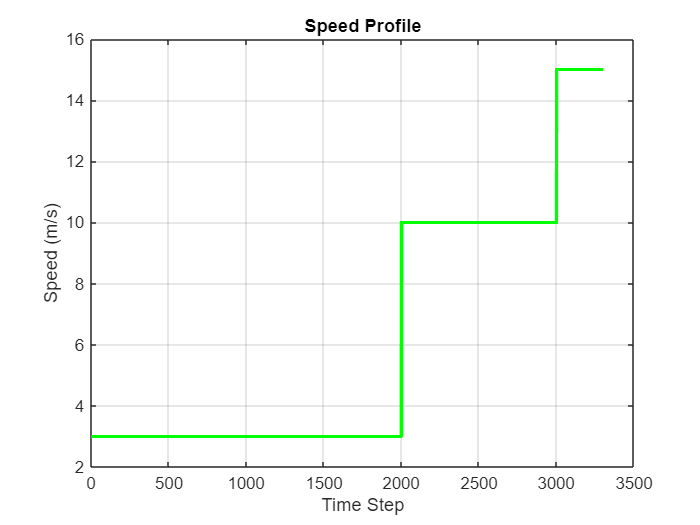


% Speed Profile Visualization
figure;
plot(1:length(v_profile), v_profile, 'g-', 'LineWidth', 2);
xlabel('Time Step');
ylabel('Speed (m/s)');
title('Speed Profile');
grid on;